# Изменение тона аудио-файла

### Задание основных параметров системных объектов:

% Загрузка коэффициентов фильтров
Data = load('nummat.mat');
Nummat = Data.nummat;
% Параметры и системные объекты чтения файла
SamplesPerFrame = 100;
fileInfo = audioinfo('funky-guitar.wav');
fileReader = dsp.AudioFileReader('funky-guitar.wav');
fileReader.SamplesPerFrame = SamplesPerFrame;
% Системный объект воспроизведения
deviceWriter = audioDeviceWriter('SampleRate', fileInfo.SampleRate);
% Системный объект КИХ-фильтра с изменяемыми коэффициентами
Hd = dsp.FIRFilter('Structure','Direct form symmetric','NumeratorSource','Input port');

### Основной цикл обработки:

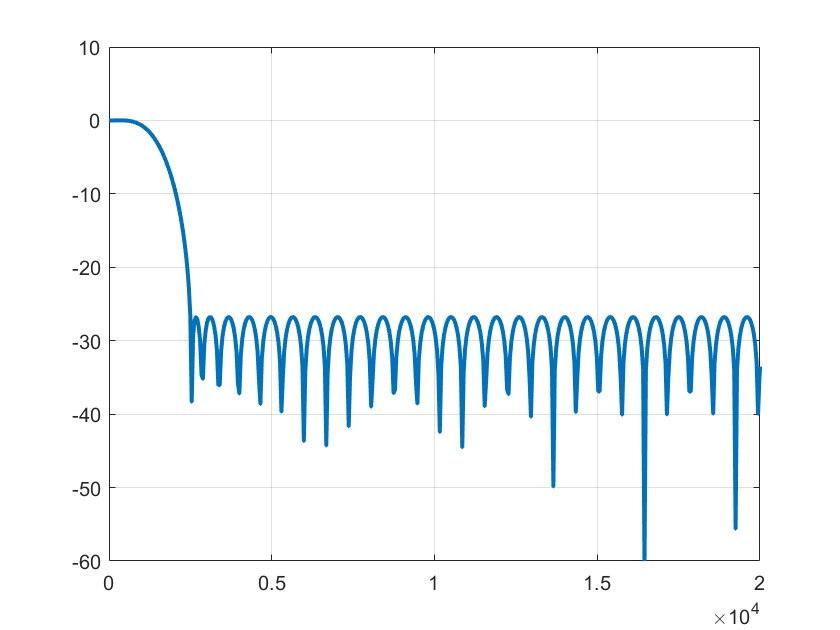

Num = Nummat(2,:);
[h,f] = freqz(Num,1,[],fileInfo.SampleRate);
plot(f,10*log10(abs(h)),'LineWidth',2); grid on; xlim([0 20e3]); ylim([-60 10]);


while ~isDone(fileReader)
    audioData  = fileReader(); 
    audioData  = Hd(audioData,Num); 
    deviceWriter(audioData);
end

reset(fileReader);
reset(deviceWriter);